# Projekt 5

## Nastavitev parametrov

% Definicija parametrov
T = 0.01;
N = 300;
N_APRBS = 3000;
amplitude_train = 2.5;
amplitude_test = 2.0;
Th = 0.20;
padding = 100;
dV = 0.05;
c = zeros(2 / dV + 1, 1);

## Statična karaktersitika

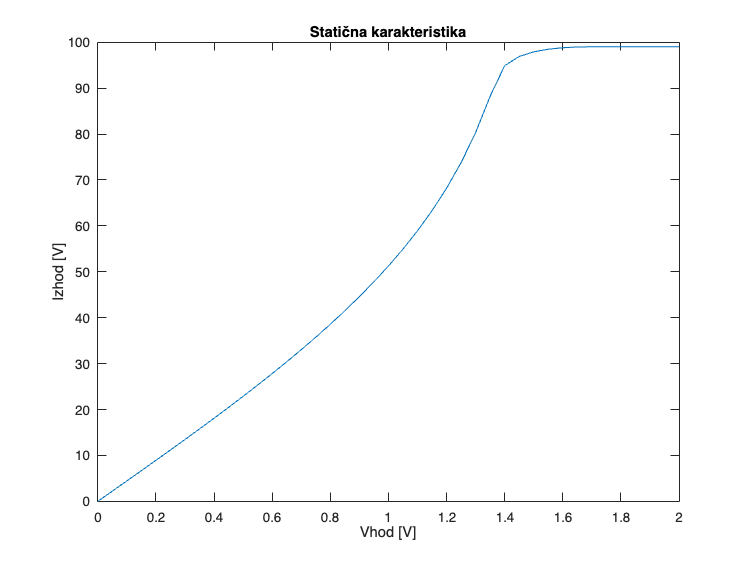

% Zanka za različne vrednosti V
for V = 0:dV:2
    u = ones(N, 1) * V;

    % Inicializacija stanja
    x = [0, 0];

    % Inicializacija izhodnega vektorja
    y = zeros(N, 1);

    % Simulacija helicrana
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u(i), x);

        % Posodobitev stanja
        x = [fip_, fi_];

        % Shranjevanje izhoda
        y(i) = fi_;
    end

    % Izračun povprečja izhodnih vrednosti po prehodnem obdobju
    y_m = mean(y(100:end));

    % Shranjevanje rezultata v c
    c(round(V/dV) + 1) = y_m;
end

% Risanje rezultata
figure;
plot(0:dV:2, c);
title("Statična karakteristika");
xlabel("Vhod [V]");
ylabel("Izhod [V]");

## Generiranje in risanje APRBS signala

% Parametri
N = 1000; % Število vzorcev
Th = 2; % Časovna konstanta
T = 0.1; % Čas vzorčenja
amplitude_train = 2.5;
amplitude_test = 2.5;
padding = 100;
N_APRBS = N; % Število APRBS vzorcev

% Generiranje APRBS signala za treniranje
u_train = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

d_train = diff(u_train);
idx_train = find(d_train) + 1;
idx_train = [1; idx_train];
for ii = 1:length(idx_train) - 1
    u_train(idx_train(ii):idx_train(ii + 1) - 1) = amplitude_train * rand;
end
u_train(idx_train(end):end) = amplitude_train * rand;
u_train = [zeros(padding, 1); u_train];
u_train = u_train - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri testu more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Generiranje APRBS signala za testiranje
u_test = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

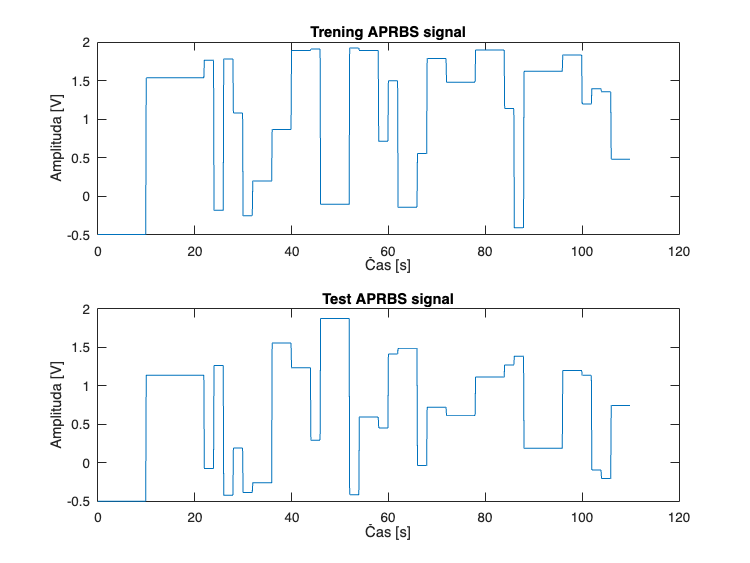

d_test = diff(u_test);
idx_test = find(d_test) + 1;
idx_test = [1; idx_test];
for ii = 1:length(idx_test) - 1
    u_test(idx_test(ii):idx_test(ii + 1) - 1) = amplitude_test * rand;
end
u_test(idx_test(end):end) = amplitude_test * rand;
u_test = [zeros(padding, 1); u_test];
u_test = u_test - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri train more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Časovni vektorji
t_train = (0:length(u_train)-1) * T;
t_test = (0:length(u_test)-1) * T;

% Risanje rezultatov
figure
subplot(2, 1, 1);
plot(t_train, u_train);
title("Trening APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

subplot(2, 1, 2);
plot(t_test, u_test);
title("Test APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

## odziv sistema na vhodni signal

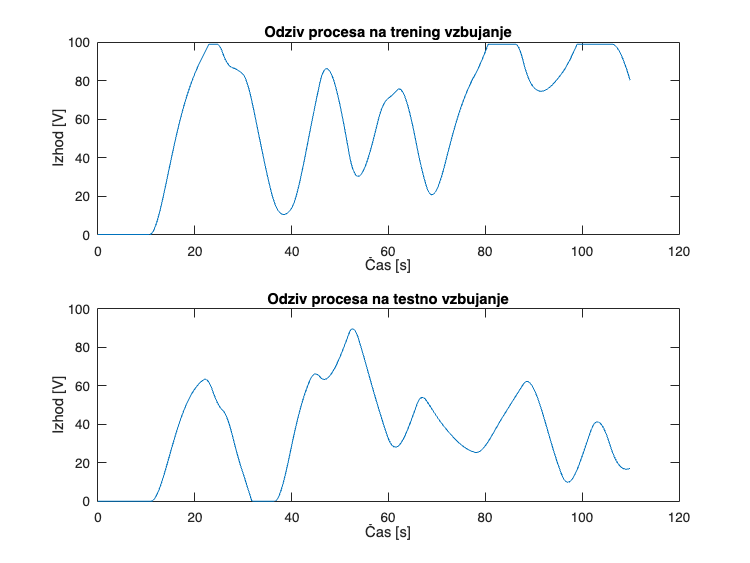


% Simulacija odziva sistema za treniranje in testiranje
y_train = simulate_helicrane(u_train, [0 0]);
y_test = simulate_helicrane(u_test, [0 0]);

% Risanje rezultatov simulacije
figure
subplot(2, 1, 1);
plot(t_train, y_train);
title("Odziv procesa na trening vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");

subplot(2, 1, 2);
plot(t_test, y_test);
title("Odziv procesa na testno vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");


% Preverjanje dolžine vektorjev u_train in y_train
if length(u_train) > 2 && length(y_train) > 2
    % Priprava vhodnih in izhodnih podatkov za učenje
    X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
    Y_train_podatki = y_train(3:end);

    % Premešanje podatkov za učenje
    perm_indeksi = randperm(size(X_train_podatki, 1));
    X_train_premesani = X_train_podatki(perm_indeksi, :);
    Y_train_premesani = Y_train_podatki(perm_indeksi, :);

    % Priprava vhodnih in izhodnih podatkov za testiranje
    X_test_podatki = [u_test(2:end-1), u_test(1:end-2), -y_test(2:end-1), -y_test(1:end-2)];
    Y_test_podatki = y_test(3:end);

    % Simulacija helicrana brez uporabe funkcije
    % Inicializacija stanja
    zacetno_stanje = [0, 0];

    % Dolžina vhoda
    N = length(u_train); % Tu mora biti dolžina u_train

    % Inicializacija izhoda
    izhodi = zeros(N, 1);

    % Glavna zanka za simulacijo
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u_train(i), zacetno_stanje);

        % Posodobitev stanja
        zacetno_stanje = [fip_, fi_];

        % Shranjevanje izhoda
        izhodi(i) = fi_;
    end

    % Prikaz končnih izhodov (izhodi)
    disp(izhodi);
else
    disp('Napaka: u_train ali y_train nimata dovolj elementov.');
end

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0

## nevronska mreža

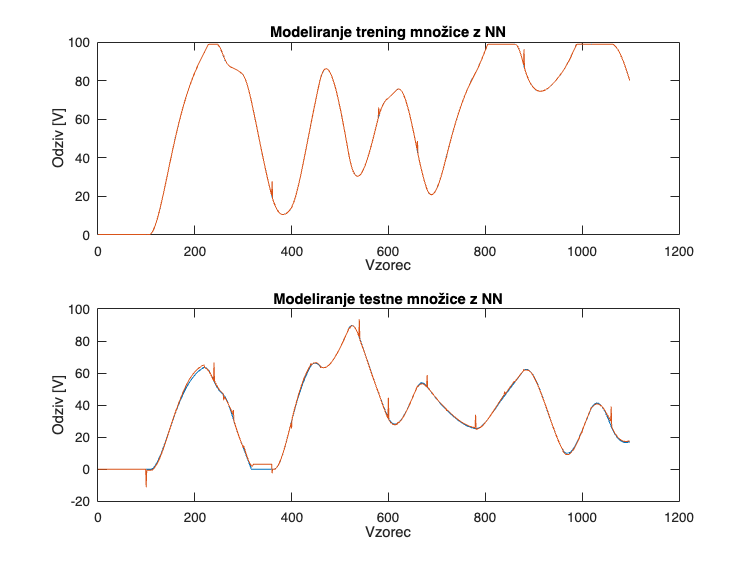

net = feedforwardnet([15, 12, 10]);
net.layers{1}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'tansig';
net.layers{3}.transferFcn = 'poslin';
net.trainParam.showWindow = false;
net.trainParam.goal = 2e-6;
[net, ~] = train(net, X_train_podatki', Y_train_podatki');

% Napovedovanje na trening množici
Y_pred_train = net(X_train_podatki');

% Napovedovanje na testni množici
Y_pred_test = net(X_test_podatki');

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(Y_train_podatki);
title("Modeliranje trening množice z NN");
hold on;
plot(Y_pred_train);
xlabel("Vzorec");
ylabel("Odziv [V]");

subplot(2, 1, 2);
plot(Y_test_podatki);
title("Modeliranje testne množice z NN");
hold on;
plot(Y_pred_test);
xlabel("Vzorec");
ylabel("Odziv [V]");

## Takagi Sugeno model

% Adjusted Takagi Sugeno model

% 1) Prepare input (X_train) and output (Y_train) data
X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
Y_train_podatki = y_train(3:end);

[X_train_podatki, mu_X_train, sigma_X_train] = normalize(X_train_podatki);
[Y_train_podatki, mu_Y_train, sigma_Y_train] = normalize(Y_train_podatki);

% Prepare the test data with the same normalization parameters
X_test_podatki = [u_test(2:end-1), u_test(1:end-2), -y_test(2:end-1), -y_test(1:end-2)];
X_test_podatki = (X_test_podatki - mu_X_train) ./ sigma_X_train; % Normalize using training parameters


% Adjusted model parameters
R = 4; % Reduced number of rules
alpha_initial = 0.001;  % Increased initial learning rate
alpha_decay = 0.995;    % Slower decay rate
epochs = 300;           % Reduced number of epochs

% Initialize parameters
[C, U] = fcm(X_train_podatki, R); % K-means for membership function centers

Iteration count = 1, obj. fcn = 1430.58
Iteration count = 2, obj. fcn = 1095.67
Iteration count = 3, obj. fcn = 1090.36
Iteration count = 4, obj. fcn = 1065.63
Iteration count = 5, obj. fcn = 987.87
Iteration count = 6, obj. fcn = 894.775
Iteration count = 7, obj. fcn = 851.325
Iteration count = 8, obj. fcn = 828.528
Iteration count = 9, obj. fcn = 804.576
Iteration count = 10, obj. fcn = 778.166
Iteration count = 11, obj. fcn = 750.822
Iteration count = 12, obj. fcn = 716.23
Iteration count = 13, obj. fcn = 664.713
Iteration count = 14, obj. fcn = 589.149
Iteration count = 15, obj. fcn = 513.293
Iteration count = 16, obj. fcn = 475.013
Iteration count = 17, obj. fcn = 465.347
Iteration count = 18, obj. fcn = 463.784
Iteration count = 19, obj. fcn = 463.549
Iteration count = 20, obj. fcn = 463.51
Iteration count = 21, obj. fcn = 463.503
Iteration count = 22, obj. fcn = 463.502
Iteration count = 23, obj. fcn = 463.502
Iteration count = 24, obj. fcn = 463.502
Iteration count = 25, obj. f

O = ones(R, 1) * std(X_train_podatki); % Membership function widths
W = rand(R, size(X_train_podatki, 2)) * 2 - 1; % Weights
b = rand(R, 1) * 2 - 1; % Biases


% Training TS model with validation checks
for epoch = 1:epochs
    alpha = alpha_initial * (alpha_decay ^ epoch);
    e_avg = 0;
    for j = 1:size(X_train_podatki, 1)
        [C, O, W, b, e] = TS_train_single(C, O, W, b, X_train_podatki(j, :)', Y_train_podatki(j), alpha);
        e_avg = e_avg + e;
    end
    e_avg = e_avg / size(X_train_podatki, 1);
    
    if mod(epoch, 50) == 0
        fprintf("Epoka %d: Povprečna napaka: %f\n", epoch, e_avg);
    end
end

Epoka 50: Povprečna napaka: 0.002201
Epoka 100: Povprečna napaka: 0.001303
Epoka 150: Povprečna napaka: 0.001028
Epoka 200: Povprečna napaka: 0.000887
Epoka 250: Povprečna napaka: 0.000802
Epoka 300: Povprečna napaka: 0.000747



fprintf("Končna povprečna napaka: %f\n", e_avg);

Končna povprečna napaka: 0.000747


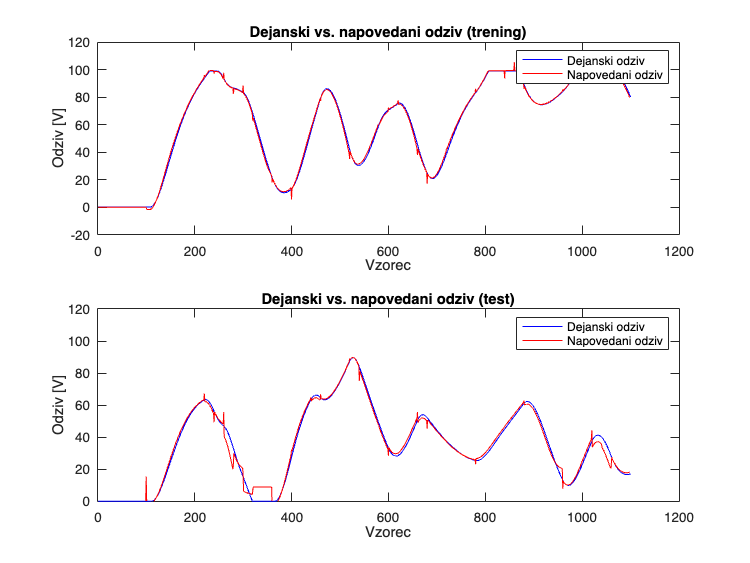


% Prediction on training and test data
Y_pred_train = TS_eval(C, O, W, b, X_train_podatki');
Y_pred_test = TS_eval(C, O, W, b, X_test_podatki');

% Denormalization of predictions
Y_pred_train = (Y_pred_train * sigma_Y_train) + mu_Y_train;
Y_pred_test = (Y_pred_test * sigma_Y_train) + mu_Y_train;

% Plotting results
figure;
subplot(2, 1, 1);
plot(y_train, 'b', 'DisplayName', 'Dejanski odziv');
hold on;
plot(Y_pred_train, 'r', 'DisplayName', 'Napovedani odziv');
title('Dejanski vs. napovedani odziv (trening)');
xlabel('Vzorec');
ylabel('Odziv [V]');
legend('show'); % Prikaže legendo

% Test data plot with modified y-axis limits
subplot(2, 1, 2);
plot(y_test, 'b', 'DisplayName', 'Dejanski odziv');
hold on;
plot(Y_pred_test, 'r', 'DisplayName', 'Napovedani odziv');
title('Dejanski vs. napovedani odziv (test)');
xlabel('Vzorec');
ylabel('Odziv [V]');
legend('show'); % Display legend
ylim([0 120]); % Set custom y-axis limits for the test plot

% shranjevanje mehkega modela
save('ts_model.mat', 'C', 'O', 'W', 'b');



function [C, O , W, b, e] = TS_train_single(C, O, W, b, X, Y, alpha)
    mu = exp(-0.5 * sum((X' - C).^2 ./ (O.^2), 2)); % mu - column vector
    
    % Prevent numerical instability
    if sum(mu) < 1e-6
        mu = mu + 1e-6;
    end
    
    mu = mu / sum(mu); % Normalization
    
    s = W * X + b; % Weighted sum
    y = sum(mu .* s); % Output

    % Compute gradients
    dmu_dC = (X' - C) ./ (O.^2) .* mu;
    dmu_dO = (X' - C).^2 ./ (O.^3) .* mu;
    
    % Chain rule to compute gradients for the TS model parameters
    dy_dC = dmu_dC .* (s - sum(s .* mu)) ./ (sum(mu).^2);
    dy_dO = dmu_dO .* (s - sum(s .* mu)) ./ (sum(mu).^2);
    
    dy_db = mu;
    dy_dW = mu * X';
    
    % Compute error
    e = (Y - y).^2;
    
    % Update parameters with learning rate alpha
    C = C - alpha .* (-2 * (Y - y) * dy_dC);
    O = O - alpha .* (-2 * (Y - y) * dy_dO);
    b = b - alpha .* (-2 * (Y - y) * dy_db);
    W = W - alpha .* (-2 * (Y - y) * dy_dW);
end

function [Y] = TS_eval(C, O, W, b, X)
    N = size(X, 2);
    Y = zeros(1, N);
    for i = 1:N
        mu = exp(-0.5 * sum((X(:, i)' - C).^2 ./ (O.^2), 2)); % Uporabite celoten vektor X
        mu = mu / sum(mu); % Normalizacija pripadnosti
        
        s = W * X(:, i) + b;
        Y(i) = sum(mu .* s);
    end
end

function [X_norm, mu, sigma] = normalize(X)
    mu = mean(X, 1);
    sigma = std(X, 0, 1);
    X_norm = (X - mu) ./ sigma;
end

